trainImgs = loadMNISTImages('train-images-idx3-ubyte');  % training set images (9912422 bytes)
trainLbls = loadMNISTLabels('train-labels-idx1-ubyte');  % training set labels (28881 bytes)

testImgs = loadMNISTImages('t10k-images-idx3-ubyte');    % test set images (1648877 bytes)
testLbls = loadMNISTLabels('t10k-labels-idx1-ubyte');   % test set labels (4542 bytes)

**Prior **= 5923/60,000 = P(c) of each class

**Posterior**:  P(c|x) = probability that image is of class is c, given the data x

**Likelihood**: P(x|c) = probability that a random instance of class Ci will take the value X

X is an image

P(C|X) = probability that image is of class c given the data (X)

C_hat  = argmax( P(C)*P(X|C) )

Choose class that is most frequent for the given X

P(C|X) = argmax( P(C)*P(X|C) / P(X) )

Choose class most likely to have produced X, while accounting for relative frequency of C

argmax( *P(C|X)* ) = argmax( *P(C)*P(X|C)* )

**Challenge: How to learn P(X|C)?**

This will not be known beforehand and must be learned from examples of X that belong to class C.

**Answer: **The joint probability is the product of the marginal probabilities.

So we estimate *P(Xi | C)* using conventional max -ikelihood estimation

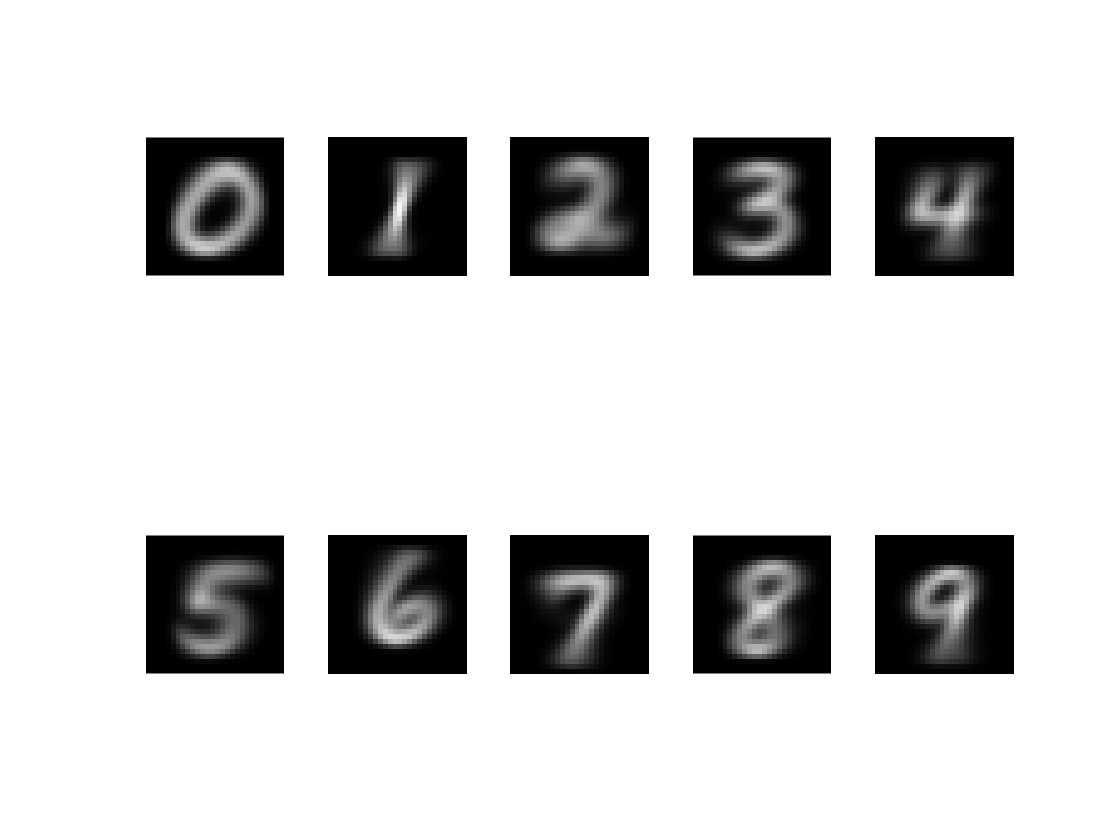

class_means = zeros(784,10); 
class_vars =  zeros(784,10); 
C = cell(1,10);
mean_plots = zeros(784,10);
for c = 0:9 
    C{c+1} = find(trainLbls==c); % find indices of images with label 'c'
    X = trainImgs(:, C{1,c+1}); % X(c) = all training images of class c = 0, 1, ... , 9
    D = size(X, 1);
    n = size(X, 2);
    mu = mean(X,2); % get the mean for each pixel
    mean_plots(:,c+1) = mu;
    variance = var(X,0,2);
    
    class_means(:,c+1) = mu; 
    class_vars(:,c+1) = variance;
end

% Plot the means
for i = 1 : 10
    subplot(2,5,i)
    imshow(reshape(mean_plots(:,i), [28 28] ))
end

% Build a Gaussian model to estimate the likelihood probability P(x|c)
final_probs = zeros(784,10); % output probabilities of (prior*posterior)
final_sums = zeros(1,10);
testClasses = zeros(10000,1); 
priors = [];
for tenK = 1 : 10000 % for pixel in test image 'tenK', get probabilty pixel in class (given its mean & variance)
    test = testImgs(:,tenK);
    for class = 1 : 10
        prior = length(find(testLbls==class-1)) / 10000;
        priors(class) = length(find(testLbls==class-1));
        for pixel = 1 : 784
            % I TRIED TWO METHODS, normpdf() METHOD IS COMMENTED OUT
            var = class_vars(pixel,class);
            avg = class_means(pixel,class);
            x = test(pixel);
            post = (-log(2*pi*var^2) - (1/(2*var^2) * (x-avg)^2)) ;
            % post = normpdf( test(pixel), class_means(pixel,class), class_vars(pixel,class) ); 
            % post = log(post); 
            final_probs(pixel,class) = post + log(prior);
        end
        
        % Get the sum of final_probs(:,class) without Infs or NaNs
        arr = zeros(784,1);
        for iter = 1 : size( final_probs(:,class), 1) %784
            if final_probs(iter,class)<Inf && final_probs(iter,class)>-Inf
                arr(iter) = final_probs(iter,class);
            else 
                continue
            end
        end
        final_sums(class) = sum(arr); 
        
    end
    % the image belongs to class 'IDX' 
    [~, IDX] = max(final_sums);
    testClasses(tenK,1) = IDX;
end

% Classification accuracy by class
classes = zeros(1,10);
for j = 1 : 10000
    for Class = 1 : 10
        if testLbls(j) == Class && testClasses(j) == Class
            classes(Class) = classes(Class) + 1;
        end
    end
end
class_acc = classes ./ priors;


% Classification accuracy of total
acc = sum(testLbls==testClasses) / 10000;

% Apply PCA followed by both full and diagonal covariance matrix Gaussian classifier. 
% Select the number of eigen-vectors that capture 95% of the information present on the 
% eigen-values. Report both classification accuracy by class and the total.

% take PCA of test and training images
dims = 50;
mu = mean(trainImgs,2);
centered = trainImgs - mu;
covariance = centered * centered';
[U,~] = eig(covariance);
X_train = U(:, 1:dims)' * trainImgs;
X_test  = U(:, 1:dims)' * testImgs;

trainImgs = X_train;
testImgs = X_test;

% Now repeat same steps as above for Gaussian classifier
class_means = zeros(dims,10); 
class_vars =  zeros(dims,10); 
C = cell(1,10);
mean_plots = zeros(dims,10);
for c = 0:9 
    C{c+1} = find(trainLbls==c); % find indices of images with label 'c'
    X = trainImgs(:, C{1,c+1}); % X(c) = all training images of class c = 0, 1, ... , 9
    D = size(X, 1);
    n = size(X, 2);
    mu = mean(X,2); % get the mean for each pixel
    mean_plots(:,c+1) = mu;
    variance = var(X,0,2);
    
    class_means(:,c+1) = mu; 
    class_vars(:,c+1) = variance;
end

Index in position 1 is invalid. Array indices must be positive integers or logical values.

'var' appears to be both a function and a variable. If this is unintentional, use 'clear var' to remove the variable 'var' from the workspace.


% Plot the means
for i = 1 : 10
    subplot(2,5,i)
    imshow(reshape(mean_plots(:,i), [28 28] ))
end

% Build a Gaussian model to estimate the likelihood probability P(x|c)
final_probs = zeros(dims,10); % output probabilities of (prior*posterior)
final_sums = zeros(1,10);
testClasses = zeros(10000,1); 
priors = [];
for tenK = 1 : 10000 % for pixel in test image 'tenK', get probabilty pixel in class (given its mean & variance)
    test = testImgs(:,tenK);
    for class = 1 : 10
        prior = length(find(testLbls==class-1)) / 10000;
        priors(class) = length(find(testLbls==class-1));
        for pixel = 1 : dims
            % I TRIED TWO METHODS, normpdf() METHOD IS COMMENTED OUT
            var = class_vars(pixel,class);
            avg = class_means(pixel,class);
            x = test(pixel);
            post = (-log(2*pi*var^2) - (1/(2*var^2) * (x-avg)^2)) ;
            % post = normpdf( test(pixel), class_means(pixel,class), class_vars(pixel,class) ); 
            % post = log(post); 
            final_probs(pixel,class) = post + log(prior);
        end
        
        % Get the sum of final_probs(:,class) without Infs or NaNs
        arr = zeros(dims,1);
        for iter = 1 : size( final_probs(:,class), 1) %784
            if final_probs(iter,class)<Inf && final_probs(iter,class)>-Inf
                arr(iter) = final_probs(iter,class);
            else 
                continue
            end
        end
        final_sums(class) = sum(arr); 
        
    end
    % the image belongs to class 'IDX' 
    [~, IDX] = max(final_sums);
    testClasses(tenK,1) = IDX;
end

% Classification accuracy by class
classes = zeros(1,10);
for j = 1 : 10000
    for Class = 1 : 10
        if testLbls(j) == Class && testClasses(j) == Class
            classes(Class) = classes(Class) + 1;
        end
    end
end
class_acc = classes ./ priors;


% Classification accuracy of total
acc = sum(testLbls==testClasses) / 10000;